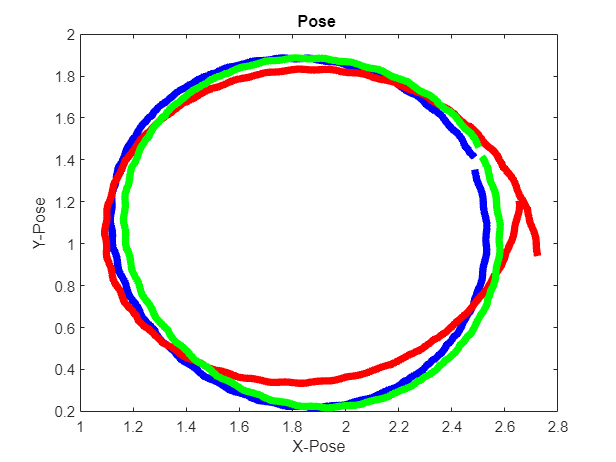

clear; % clears all var
clc; % clears command window
%data = load("third_successful.mat");
%data = load("fifth_successful.mat");
data = load("8_fking_rounds_ccw.mat");
ref = load("reference.mat");
ref_x = ref.C3(11,:);
ref_y = ref.C3(12,:);
ref_z = ref.C3(13,:);

%data = load("second_successful.mat");
lower_limit = 1715;
upper_limit = 2120;
x_1 = transpose(data.test(1715:2120,1))-0.2;
y_1 = transpose(data.test(1715:2120,2))+0.2;


x_2 = transpose(data.test(1325:1730,1));
y_2 = transpose(data.test(1325:1730,2));


x_3 = transpose(data.test(1710:2115,1))-0.15;
y_3 = transpose(data.test(1710:2115,2))+0.2;

x_ult = (x_1 + x_2 + x_3)/3;
y_ult = (y_1 + y_2 + y_3)/3;
x_g = smoothdata(x_ult,'gaussian',10);
y_g = smoothdata(y_ult,'gaussian',10);
% bod_rates = transpose(data.test(1:limit,3)); 
% motor = transpose(data.test(1:limit,4));
% motor = smoothdata(motor,'gaussian',1000);
% bod_rates_g = smoothdata(bod_rates,'gaussian',1000);
% heading = rad2deg(transpose(data.test(1:limit,5)));
% pitch = rad2deg(transpose(data.test(1:limit,6)));
% pitch = smoothdata(pitch,'gaussian',1000);
% 
% 
% 
% 
% 
% 
% plot(time,smoothedbod_roll,'Color','b','linewidth',5)
figure(1)
% plot(ref_x,ref_y,'Color','b','linewidth',5)
% xlabel('X-Pose Ref')
% ylabel('Y-Pose Ref')
% title('Ref Pose')
% axis equal


plot(x_1,y_1,'Color','b','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')
title('Pose ')

hold on
plot(x_2,y_2,'Color','r','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')


plot(x_3,y_3,'Color','g','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')


hold off 

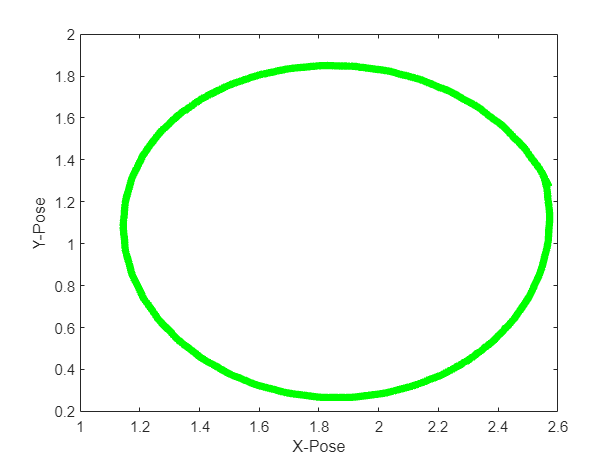



% plot(x_g,y_g,'Color','r','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% title('Pose w gaussian')
% % title('comparison')



% plot3(ref_x, ref_y, ref_z, 'Color','r','LineWidth',2);
% xlabel('X-Pose')
% ylabel('Y-Pose')
% zlabel('Z-Pose')

plot(x_ult,y_ult,'Color','g','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')

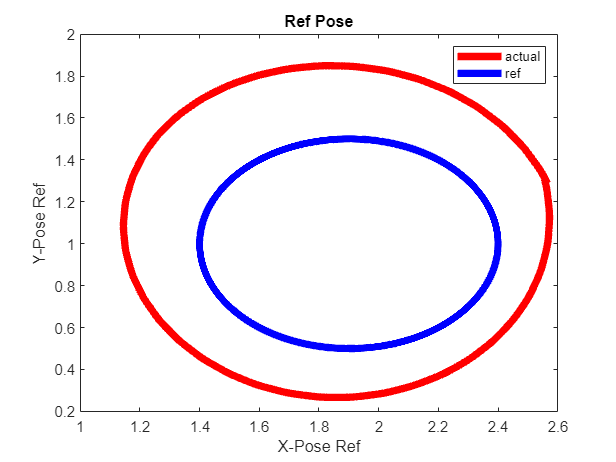



plot(x_g,y_g,'Color','r','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')
title('Pose w gaussian')
% % title('comparison')
hold on
plot(ref_x,ref_y,'Color','b','linewidth',5)
xlabel('X-Pose Ref')
ylabel('Y-Pose Ref')
title('Ref Pose')
legend('actual',"ref");
hold off


% plot(1:limit,bod_rates_g,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('Bod Rates')
% title('Rates vs index')
% plot(1:limit,motor,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('Motor')
% title('Motor vs index')
% plot(1:limit,heading,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('heading')
% title('Heading vs index')
% plot(1:limit,pitch,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('pitch')
% title('Pitch vs index')